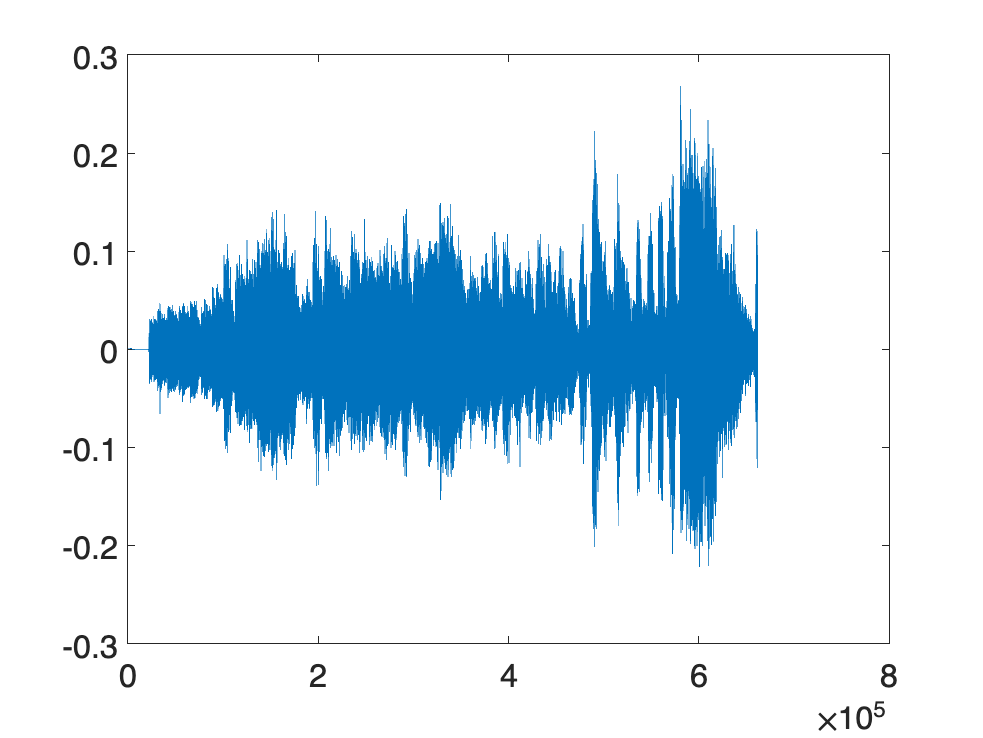

%The following reads the data file, and plots the file
[y,Fs] = audioread('PinkPanther30.wav');

%Because the sound signals have 2 channels, we will just analyze the first channel
y = y(:,1);

figure(1)
plot(y)
set(gca,'fontsize',18)

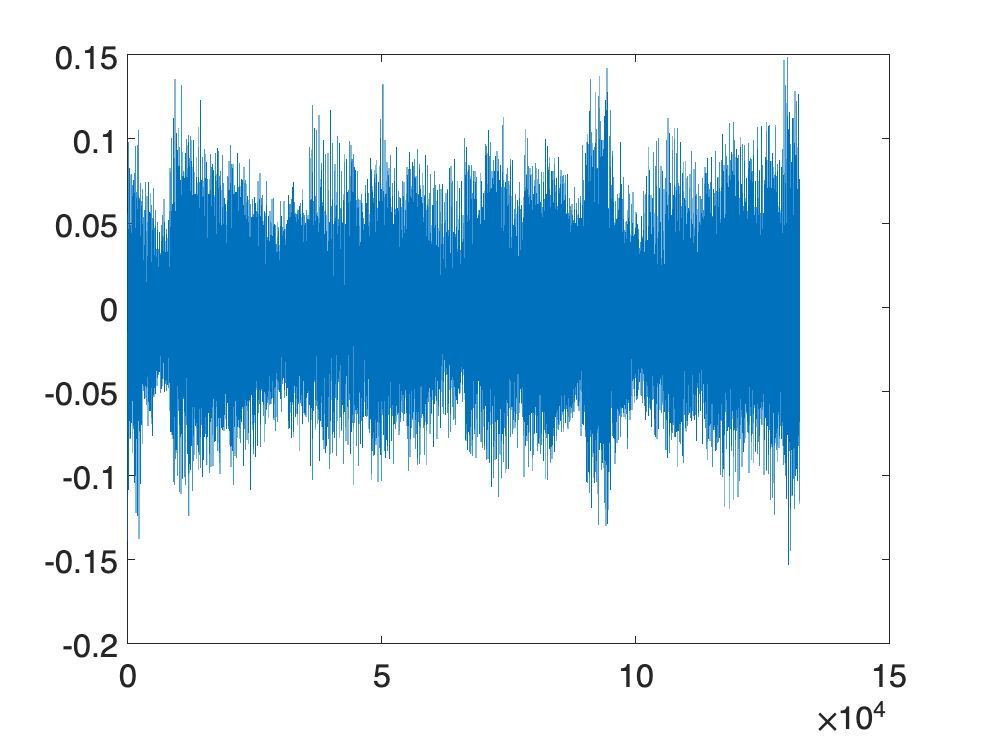


% Find the length of y
L = length(y);


% Determine starting and ending points of your clipping by looking at plot 1
% Note these must be integers that are not 0!
index1 = round(L*0.3); % CHANGE THIS NUMBER
index2 = round(L*0.5); % CHANGE THIS NUMBER

sound(y(index1:index2),Fs)  % Play the file
newsignal = y(index1:index2);  % Clips sound signal to new signal that starts at index1 and goes to index2
figure(2)
plot(newsignal)
set(gca,'fontsize',18)

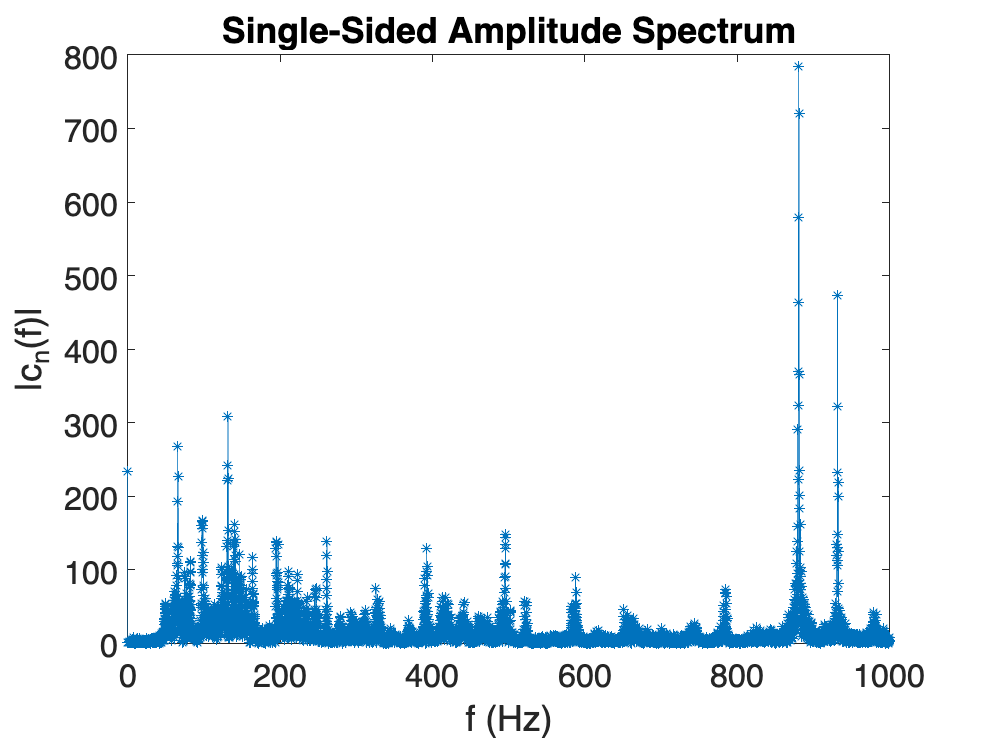

[signal,Fs] = audioread('PinkPanther30.wav');
signal = signal(:,1);
L = length(signal);
signal = signal(round(L*0.3):round(L*0.5));

% Copy the procedure in the video to get the single sided spectrum
y=fft(signal);
yMag = abs(y);
N=length(yMag);
f=0:(Fs/N):(Fs/2);
yMag=yMag(1:length(f));
% This code plots yMag as a function of f
% You can comment out this code if necessary while building your solution
figure
plot(f,yMag,'-*');
title('Single-Sided Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('|c_n(f)|')
set(gca,'fontsize',18)
xlim([0,1000])

url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_clarinet1.wav';
websave('1803_musicdata_clarinet1.wav', url);
url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_guitar1.wav';
websave('1803_musicdata_guitar1.wav', url);
url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_voice1.wav';
websave('1803_musicdata_voice1.wav', url);

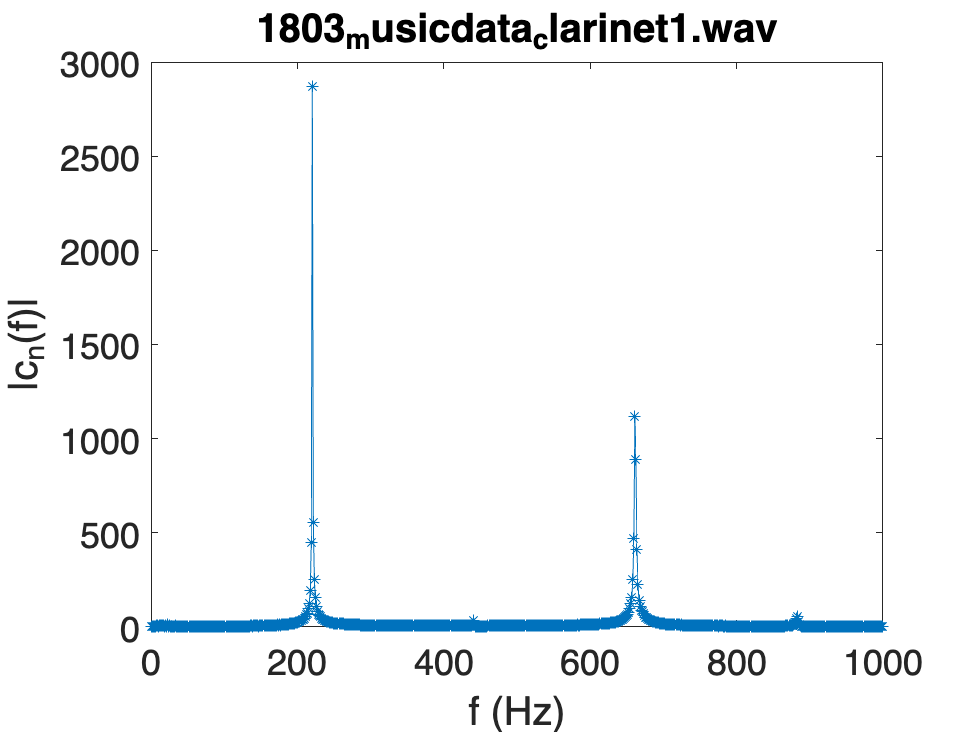

show_spectrum('1803_musicdata_clarinet1.wav', 1);

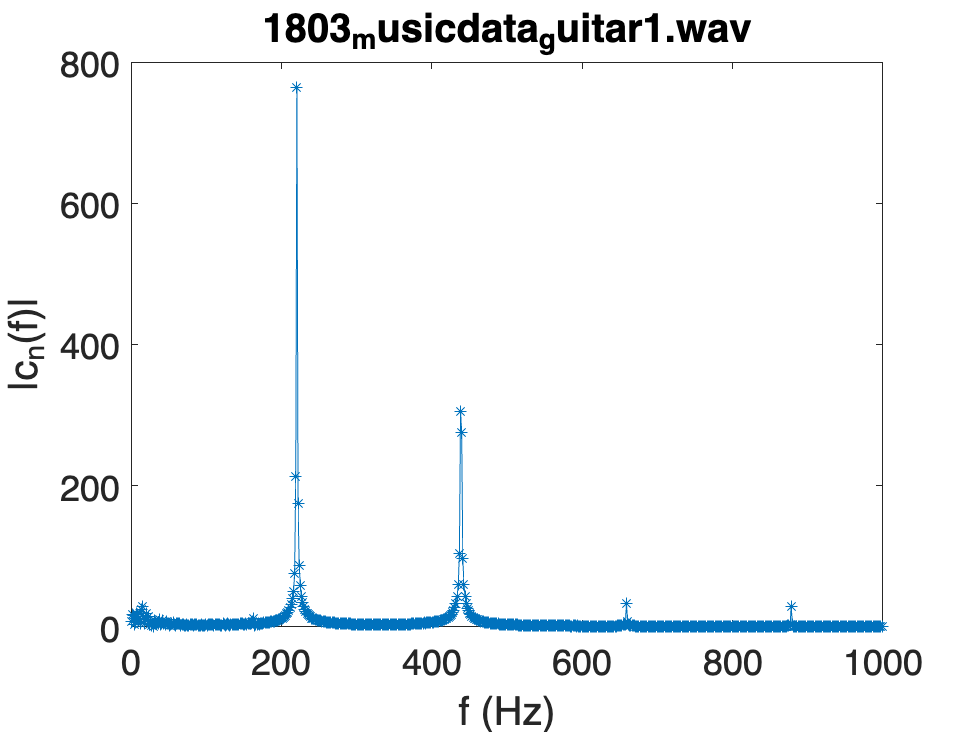

show_spectrum('1803_musicdata_guitar1.wav', 2);

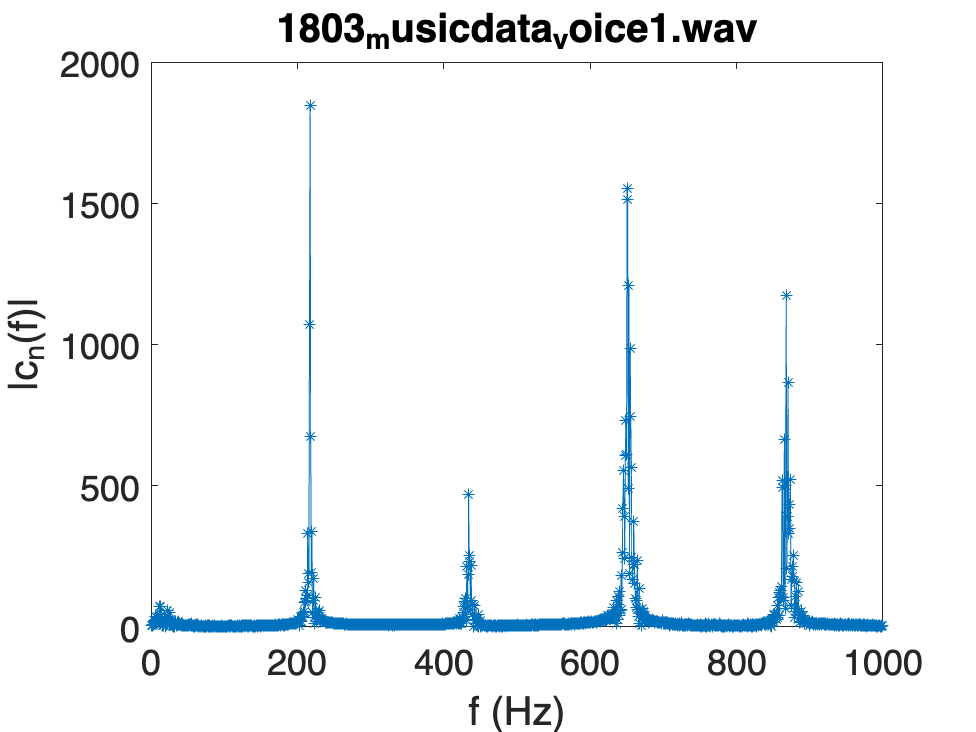

show_spectrum('1803_musicdata_voice1.wav', 3);

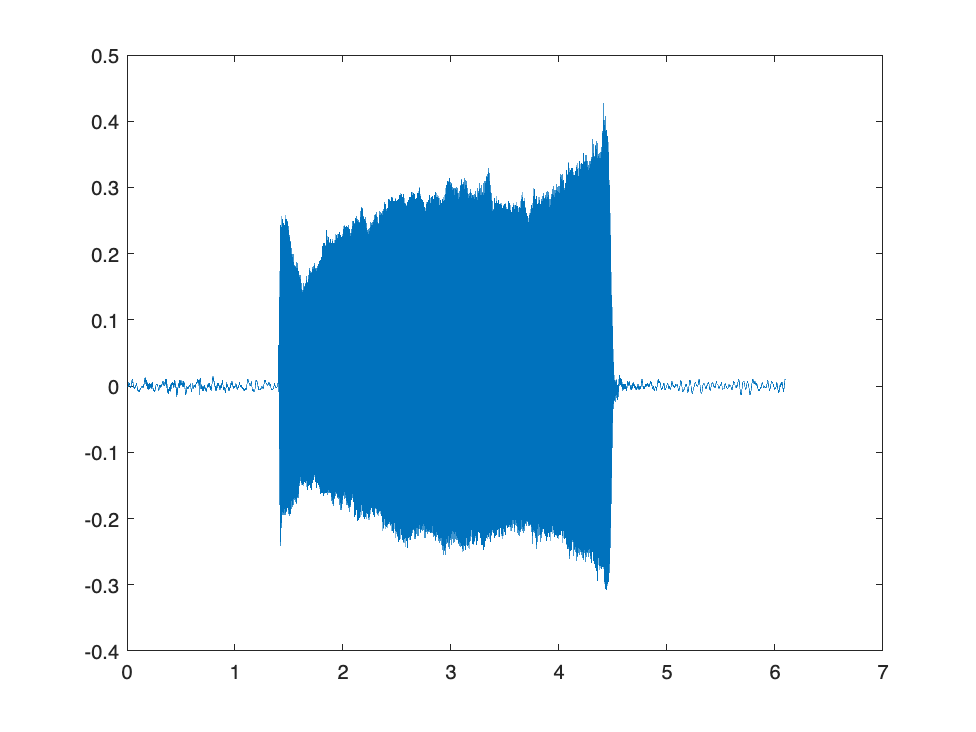

[y,Fs] = audioread('1803_musicdata_voice1.wav'); %The audio file is already loaded for you
y = y(:,1); %Take first channel of signal
% sound(y,Fs); % uncomment this command in MATLAB online to hear the sound
n = length(y);  %length of signal
t = (0:n-1)*(1/Fs);  %time series vector 

figure(1)
plot(t, y);  %plot the sound signal

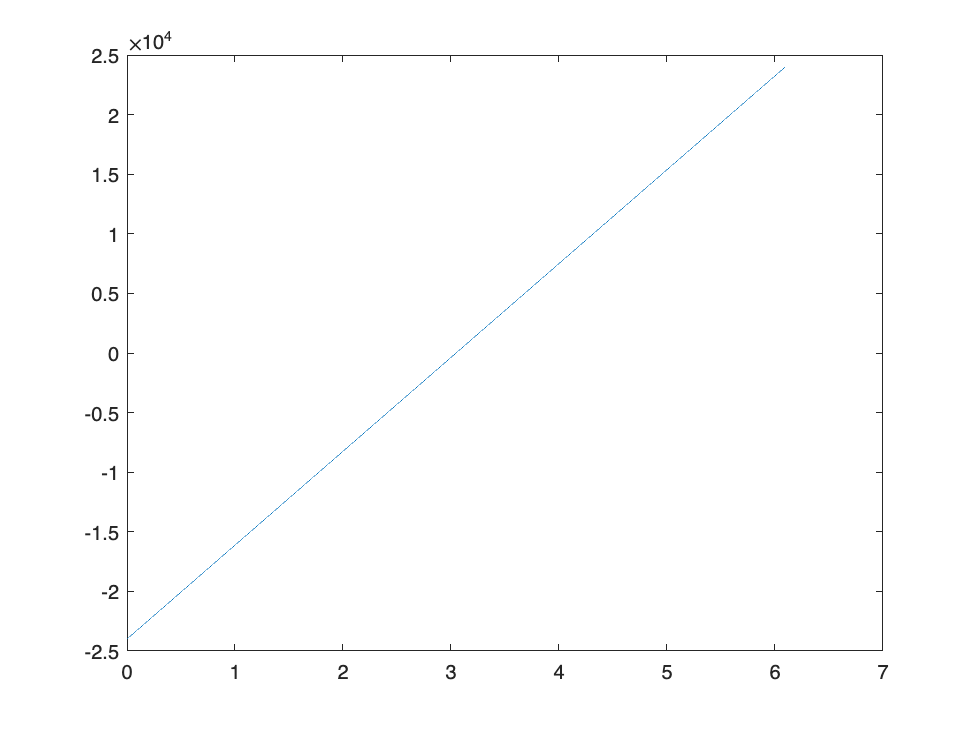


%NOTE we do not take the one sided signal here because we need both sides to 
%recreate the sound signal using ifft command

Y = fftshift(fft(y));   %Take the Fourier series and take a symmetric shift 
fshift = (-n/2:n/2-1)*(Fs/n);   %Determine the frequency vector (shifted)
L = length(fshift);             %Find the length of frequency values
Yfilt = Y;   %Take the absolute value

%YOU MODIFY Yfilt here to remove the frequencies between -300hz and 300hz
% You may find plotting fshift vs abs(Yfilt) helpful here
plot(t, fshift)

index1 = 1; %MODIFY THIS
for index = 1:L
   if index1 == 1 && fshift(index)>=-300
    index1 = index    
   end
   if fshift(index)>=300
    index2 = index
    break
   end
end

index1 = 144474

index2 = 148131


% index2 = L; %MODIFY THIS

% Sets frequencies between index1 and index2 to 0
Yfilt(index1:index2) = 0 ;




%Take the inverse FFT to create a filtered sound signal
soundFilt = ifft(ifftshift(Yfilt),'symmetric');


%Uncomment the command below to listen to your filtered sound signal in MATLAB online
sound(soundFilt,Fs);

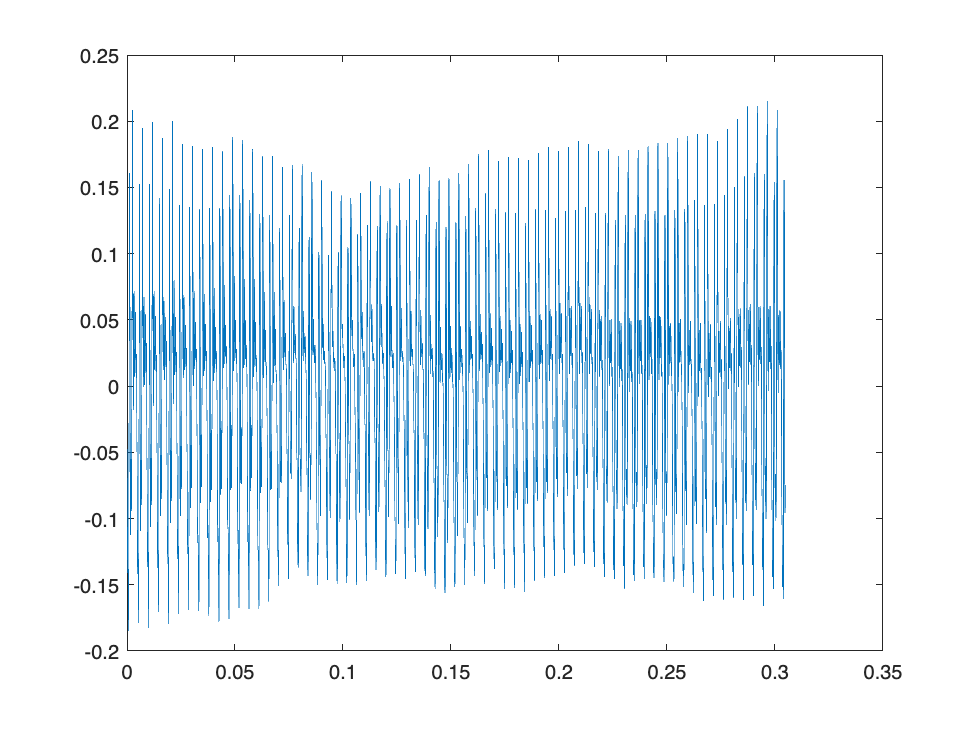

[y,Fs] = audioread("1803_musicdata_voice1.wav");
y = y(:,1);
L = length(y);
% Extract points from 30-40% time period of the file
y = y(round(L*0.25):round(L*0.3));
% New length of the file
L = length(y);

T = 1/Fs;
% Time vector
t = (0:L-1)*T;
% Plot the audio data
figure(1)
plot(t,y)


Y = fft(y);
P2 = abs(Y);
P1 = P2(1:floor(L/2+1));
P1(2:end-1) = 2*P1(2:end-1);

f = (Fs*(0:(L/2))/L); 

%Make sure our vectors are column vectors.
f = f(:);
P1 = P1(:);

%Modify the minpeak so that very small peaks in harmonics (above 1000 hz) don't show in table
minpeak = 1000

minpeak = 1000

minpeakdist = 25

minpeakdist = 25

[pks, freq, w, p] = findpeaks(P1, f, 'MinPeakProminence',minpeak, 'MinPeakDistance', minpeakdist);
audioData = table(freq, pks, w, p, 'VariableNames', {'Frequency', 'PeakHeight', 'PeakWidth', 'Prominence'})


audioData =

  0×4 empty table



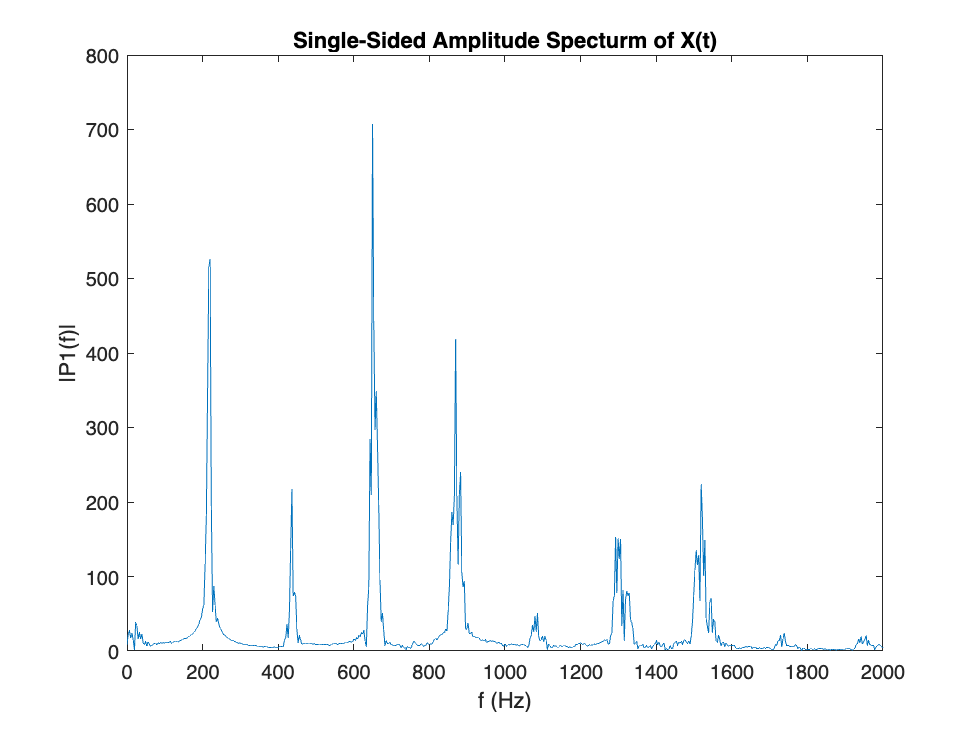



figure(2)
plot(f, P1)
title('Single-Sided Amplitude Specturm of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 2000])
hold on
plot(audioData.Frequency, audioData.PeakHeight, 'ro')
hold off

function res = show_spectrum(filename, i)

    [signal,Fs] = audioread(filename);
    signal = signal(:,1);
    Len = length(signal);
    signal = signal(round(Len*0.3):round(Len*0.5));
    L = length(signal);
                      
    y = fft(signal);
    yMag = abs(y);
    N = length(yMag);
    f = 0: (Fs/N) : (Fs/2);
    yMag = yMag(1:length(f));
    
    figure(i)
    p = plot(f,yMag,'-*');
    title(filename)
    xlabel('f (Hz)')
    ylabel('|c_n(f)|')
    set(gca,'fontsize',18)
    xlim([0,1000])
    res = p;
end